**P.65**

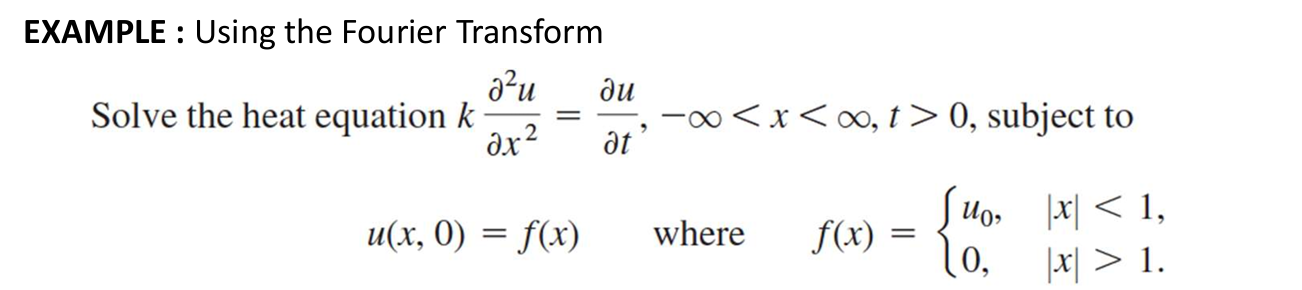

clear
clc
clearvars
syms w k u(x,t) U(w,t) Y(t) F(w) u0
Dt = diff(u,t);
D2x = diff(u,x,2);
eqn = fourier(Dt == k*D2x,x,w);
eqn = subs(eqn,{fourier(Dt,x,w),fourier(u,x,w)},{subs(Dt,{u,x},{U,w}),U})

$$eqn(t) = \frac{\partial }{\partial t}U\left(w,t\right)=-k\,w^{2}\,U\left(w,t\right)$$

eqn = subs(eqn,U(w,t),Y(t))

$$eqn(t) = \frac{\partial }{\partial t}Y\left(t\right)=-k\,w^{2}\,Y\left(t\right)$$

sol = dsolve(eqn)

$$sol = C_{1}\,{\mathrm{e}}^{-k\,t\,w^{2}}$$

sol = subs(sol,sym("C1"),F(w))

$$sol = {\mathrm{e}}^{-k\,t\,w^{2}}\,F\left(w\right)$$

F(w) = simplify(int(u0*exp(1i*w*x),x,[-1 1]))

$$F(w) = \frac{2\,u_{0}\,\sin\left(w\right)}{w}$$

u(x,t) = str2sym('1/(2*pi)')*int(sol*exp(-1i*w*x),w,[-inf inf])

$$u(x, t) = \frac{\int_{-\infty }^{\infty }{\mathrm{e}}^{-k\,t\,w^{2}}\,{\mathrm{e}}^{-w\,x\,\mathrm{i}}\,F\left(w\right)\mathrm{d}w}{2\,\pi }$$

Solution = simplify(str2sym('1/(2*pi)')*int(exp(-k*t*w^2)*cos(w*x)*F(w),w,[-inf inf]))

$$Solution = \frac{u_{0}\,\int_{-\infty }^{\infty }\frac{{\mathrm{e}}^{-k\,t\,w^{2}}\,\cos\left(w\,x\right)\,\sin\left(w\right)}{w}\mathrm{d}w}{\pi }$$